# Vapor-Liquid Equilibrium (VLE)

Pascal Denis — Centrale Marseille — octobre 2017

## Rappel théorique

Dans le cas d'une solution idéale et un mélange de gaz parfait, on peut utiliser la loi de Raoult (1) : 


$$y_i\cdot P = x_i\cdot P^{sat}_i(T) 
$$


Pour analyser l'équilibre liquide-vapeur du binaire éthanol - butanol, il est donc nécessaire de faire appel à  des données expérimentales pour confirmer ou infirmer le modèle choisi. 

les bases de données pour obtenir des données expérimentales sont : 

DDBST : [Dortmund Data Bank](http://www.ddbst.com/ddbst.html) 

- Très vaste choix de données d'équilibre VLE, LLE

- Base de données payante pour une grande partie des données

- Le logiciel de base permet d'accéder aux références des équilibres.

- Références fournies

KDB : [Korean Data Bank](https://www.cheric.org/research/kdb/) (gratuite, faisant partie du CHERIC : Chemical Engineering & Material Research Infomation Center)

## Choix du  binaire et  données d'équilibre

Le binaire choisi est le mélange éthanol / n-butanol (ou 1-butanol). On trouve respectivement : 

- DDBST : [Vapor-Liquid Equilibrium Data Set 507](http://www.ddbst.com/en/EED/VLE/VLE%20Ethanol%3B1-Butanol.php)

- KDB : [Isobaric P-T-X-Y Data : ETHANOL + N-BUTANOL at 760mmHg](https://www.cheric.org/research/kdb/hcvle/showvle.php?vleid=340) 

% Attention la température est  en °F !
% les colonnes sont : 
% T, P, x, y, erreur T, erreur P, erreur x, erreur y

KDB = 'Korean Data Bank';

VLE_KDB = [177.4 760 0.880 0.968 0.1 0.003 0.003
184.7 760 0.709	0.912 0.1 0.003 0.003
189.8 760 0.610	0.871 0.1 0.003 0.003
198.3 760 0.468	0.786 0.1 0.003 0.003
211.3 760 0.282	0.602 0.1 0.003 0.003
225.7 760 0.129	0.384 0.1 0.003 0.003
199.3 760 0.453	0.779 0.1 0.003 0.003
215.8 760 0.233	0.563 0.1 0.003 0.003
204.4 760 0.357	0.696 0.1 0.003 0.003];

% Passage en Kelvin 
VLE_KDB(:,1) = VLE_KDB(:,1) *5/9 - 32 + 273.15;


% Brunjes A.S.; Bogart M.J.P.: The Binary Systems Ethanol-n-Butanol, Acetone-Water and Isopropanol-Water. Ind.Eng.Chem. 35 (1943) 255-260
DDBST_Brunjes = 'Brunjes A.S.; Bogart M.J.P.: The Binary Systems Ethanol-n-Butanol, Acetone-Water and Isopropanol-Water. Ind.Eng.Chem. 35 (1943) 255-260';

VLE_DDBST_Brunjes = [387.45 0.06200	0.18100
384.25	0.11300	0.31600
379.05	0.17800	0.49600
374.45	0.25200	0.59700
369.55	0.32300	0.70800
366.65	0.42700	0.78400
363.75	0.48800	0.82800
361.25	0.55500	0.88100
361.45	0.57400	0.88500
359.55	0.60100	0.90000
358.85	0.66600	0.92700
357.05	0.74300	0.94600
356.45	0.73800	0.97600
354.15	0.84500	0.98200
353.45	0.88700	0.98700
352.25	0.93800	0.99700];
%
% Hellwig L.R.; van Winkle M.: Vapor-Liquid Equilibria for Ethyl Alcohol Binary Systems. Ind.Eng.Chem. 45 (1953) 624-629
%

%Caîne 
DDBST_Hellwig = 'Hellwig L.R.; van Winkle M.: Vapor-Liquid Equilibria for Ethyl Alcohol Binary Systems. Ind.Eng.Chem. 45 (1953) 624-629';

VLE_DDBST_Hellwig = [380.75	0.12900	0.38400
375.25	0.23300	0.56300
372.75	0.28200	0.60200
368.95	0.35700	0.69600
366.05	0.45300	0.77900
365.55	0.46800	0.78600
360.85	0.61000	0.87100
357.95	0.70900	0.91200
353.95	0.88000	0.96800];

%
% Gay L.: (Deuxième mémoire). Chim.Ind.Genie Chim. 18 (1927) 187-203
%
DDBST_Gay = 'Gay L.: (Deuxième mémoire). Chim.Ind.Genie Chim. 18 (1927) 187-203';
VLE_DDBST_Gay = [390.75	0.00000	0.00000
388.15	0.03450	0.12500
385.65	0.06850	0.22850
383.15	0.10550	0.32700
380.65	0.14500	0.41600
378.15	0.18800	0.49600
373.15	0.28400	0.63450
368.15	0.39900	0.74950
363.15	0.53650	0.84300
360.65	0.61600	0.88300
358.15	0.70300	0.91690
355.65	0.79950	0.95080
353.15	0.90800	0.97980
351.45	1.00000	1.00000];


## Données expérimentale de pression de vapeur saturante

Plusieurs sources sont à votre disposition : 

— Perry Chemical's engineering Handbook [2,Table 2-10]

- Pression de vapeur de l'éthanol  : T_Sat_Ethanol_Perry / P_Sat_Perry

- Pas données pour le n-butanol

— CRC Handbook of chemistry and physics - [1,pp 6-97]

- Température de saturation de l'éthanol : [T_Sat_Ethanol_CRC](https://www.dawsonera.com/readonline/9781498754293/startPage/1161)

- Température de saturation du n-butanol : [T_Sat_Butanol_CRC](https://www.dawsonera.com/readonline/9781498754293/startPage/1153)

- Pression de Saturation commune : P_Sat_CRC (commune

— DDBST  ensemble de points expérimentaux : 

- [Vapor Pressure of Ethanol](http://www.ddbst.com/en/EED/PCP/VAP_C11.php) : P_Sat_Ethanol_DDBST

- [Vapor Pressure of 1-Butanol](http://www.ddbst.com/en/EED/PCP/VAP_C39.php) : P_Sat_Butanol_DDBST 

% 
% Attention  !  Pression en  kPa
% 
P_Sat_Butanol_DDBST = [295.75	0.7333
298.13	0.905
303.15	1.277
304.05	1.3732
308.18	1.809
309.35	1.973
313.85	2.613
321.35	4.133
323.25	4.593
325.55	5.280
329.44	6.540
331.45	7.373
333.27	8.091
337.51	10.100
338.95	10.852
342.29	12.910
343.45	13.812
346.65	16.185
347.69	16.850
351.13	19.870
357.54	26.700
358.25	27.731
362.36	33.045
362.59	33.370
366.81	39.974
366.85	40.030
366.95	40.463
370.31	46.230
370.51	46.601
373.70	53.090
373.89	53.450
374.32	54.436
376.79	59.932
379.37	66.280
379.52	66.632
379.65	67.594
382.04	73.331
383.35	77.140
384.31	79.856
384.34	79.930
386.58	86.807
388.41	92.750
388.47	92.995
390.54	100.142
390.57	100.210
390.95	102.125
391.30	102.830
392.34	106.705
394.09	113.412
395.71	119.945
397.31	126.628
398.15	123.100
398.84	133.322
419.34	254.731
423.15	269.200
429.11	335.690
433.77	381.995
439.24	439.041
439.28	439.447
443.97	492.946
448.15	515.300
448.63	554.957
459.75	719.306
462.64	764.497
470.31	905.744
472.55	947.794
473.15	925.700
480.96	1128.560
482.32	1158.750
490.87	1346.910
492.30	1404.470
498.15	1518.300
502.06	1683.210
502.47	1692.740
512.82	2023.360
513.06	2044.430
522.92	2404.750
523.15	2372.300
523.20	2412.550
532.85	2818.460
533.23	2827.880
542.77	3283.940
548.15	3567.100
550.64	3694.710
556.89	4053.610
562.98	4413.110];
%%
% Données sur l'éthanol
%%
P_Sat_Ethanol_DDBST = [273.15	1.5932
277.24	2.1065
277.24	2.112
278.12	2.233
278.12	2.2425
278.15	2.2395
281.45	2.760
281.55	2.800
282.15	2.920
282.45	2.9464
282.85	3.040
283.14	3.108
283.14	3.129
283.15	3.140
283.35	3.133
283.75	3.2264
284.15	3.2664
284.75	3.413
284.95	3.5064
285.25	3.5464
285.55	3.6264
286.05	3.693
286.35	3.813
286.75	3.880
287.05	3.986
287.25	4.013
287.95	4.200
288.11	4.276
288.11	4.302
288.35	4.306
289.05	4.493
289.05	4.520
289.45	4.586
289.65	4.666
289.85	4.786
290.25	4.840
290.35	4.853
290.65	4.960
291.05	5.080
291.45	5.186
291.75	5.333
291.85	5.320
292.25	5.466
292.45	5.546
292.65	5.613
293.05	5.760
293.15	5.786
293.15	5.865
293.20	5.860
293.20	5.864
293.20	5.882
293.35	5.893
293.65	5.960
293.75	6.026
294.25	6.173
294.25	6.199
294.65	6.319
294.75	6.359
294.95	6.426
295.25	6.533
295.45	6.599
295.45	6.653
295.55	6.533
295.65	6.733
295.85	6.773
295.95	6.866
296.05	6.879
296.25	6.946
296.35	7.026
296.55	7.066
296.65	7.146
298.12	7.883
298.12	7.889
298.15	7.869
303.16	10.454
303.16	10.460
303.20	10.479
307.65	13.372
308.14	13.736
308.15	13.672
308.15	13.703
308.15	13.760
308.18	13.777
308.18	13.785
313.15	17.877
313.17	17.909
313.17	17.916
314.85	19.985
315.55	20.225
318.14	23.058
318.15	23.033
318.18	23.093
318.18	23.119
319.17	24.247
319.17	24.257
321.05	26.798
323.15	29.456
323.15	29.488
323.15	29.491
325.55	33.411
328.14	37.302
328.15	37.312
329.55	39.757
329.65	40.010
333.15	46.839
335.85	53.356
338.15	58.358
338.15	58.400
338.15	58.443
340.85	66.874
341.15	67.154
343.15	72.273
345.15	80.180
348.15	88.858
348.55	93.432
349.05	93.846
350.75	99.698
350.85	100.045
351.15	101.325
351.25	101.325
351.70	102.220];

% Données du Perry 
% Attention Pression en  mmHg
% pas de données sur le n-butanol dans le Perry

T_Sat_Ethanol_Perry = [-31.3 -12.0 -2.3 8.0 19.0 26.0 34.9 48.4 63.5 78.4];
P_Sat_Ethanol_Perry = [1 5 10 20 40 60 100 200 400 760];


% Données du Perry 

P_Sat_CRC = [1 10 100 1000 10000 100000];
T_Sat_Butanol_CRC = [-37 -20 0 28 64 117.4];
T_Sat_Ethanol_CRC = [-73 -56 -34 -7 29.2 78.0];



## Équation de Pression de vapeur saturante

Un large choix d'équation est  disponible, la plus courante étant celle d'Antoine, mais pour de plus amples informations, consultez [The properties of gases and liquids](https://www.dawsonera.com/readonline/9780071499996/startPage/229) [3, Chap. 7].

Équation d'Antoine 

- Perry's [2, Table 13-4] *(La pression est  en mmHg et la température en °C)* On trouvera 2 formulations pour l'éthanol, ce qui compliquera la programmation, car elle sont sur le même domaine de température que le n-butanol.

- National Institue of Standards and technology : [WebBook de Chimie NIST](http://webbook.nist.gov/chemistry/)* (La pression est en bar et  la température en K)*

- The Properties of Gases and Liquids [3] — Appendix A, section D

Équation dérivée de Riedel (cf. [3]) 

- Korean Data Bank : [C_Ethanol_KDB](https://www.cheric.org/research/kdb/hcprop/showcoef.php?cmpid=818&prop=PVP), [C_Butanol_KDB](https://www.cheric.org/research/kdb/hcprop/showcoef.php?cmpid=821&prop=PVP) (Pression en  kPa et T en K)

- Perry's [2, Table 2-8] - Données disponibles dans la base de données Perry.mat, et fonction matlab disponible.  (Pression en  Pa et T en K)

Équation de Wagner — The Properties of Gases and Liquids [3] — Appendix A, section D

- [Coefficient pour l'éthanol](https://www.dawsonera.com/readonline/9780071499996/startPage/767) (#66)

- [Coefficient pour le butanol](https://www.dawsonera.com/readonline/9780071499996/startPage/769) (#130)

Comme vous pouvez le constater, il y a un large choix de possibilité qui peut fortement s'amenuiser en fonction des produits utilisés.  Nous travaillerons avec les données issues de KDB pour chacun des composants du binaire.

La fonction P_Sat_KDB.m est  disponible sur Moodle. 

La vérification de la bonne adéquation entre les formules et  les données expérimentales et  un préalable à toute utilisation (rappelez-vous le TD sur l'équation d'Antoine). 

## Comparaison des équations de Pression de Vapeur et  des données 

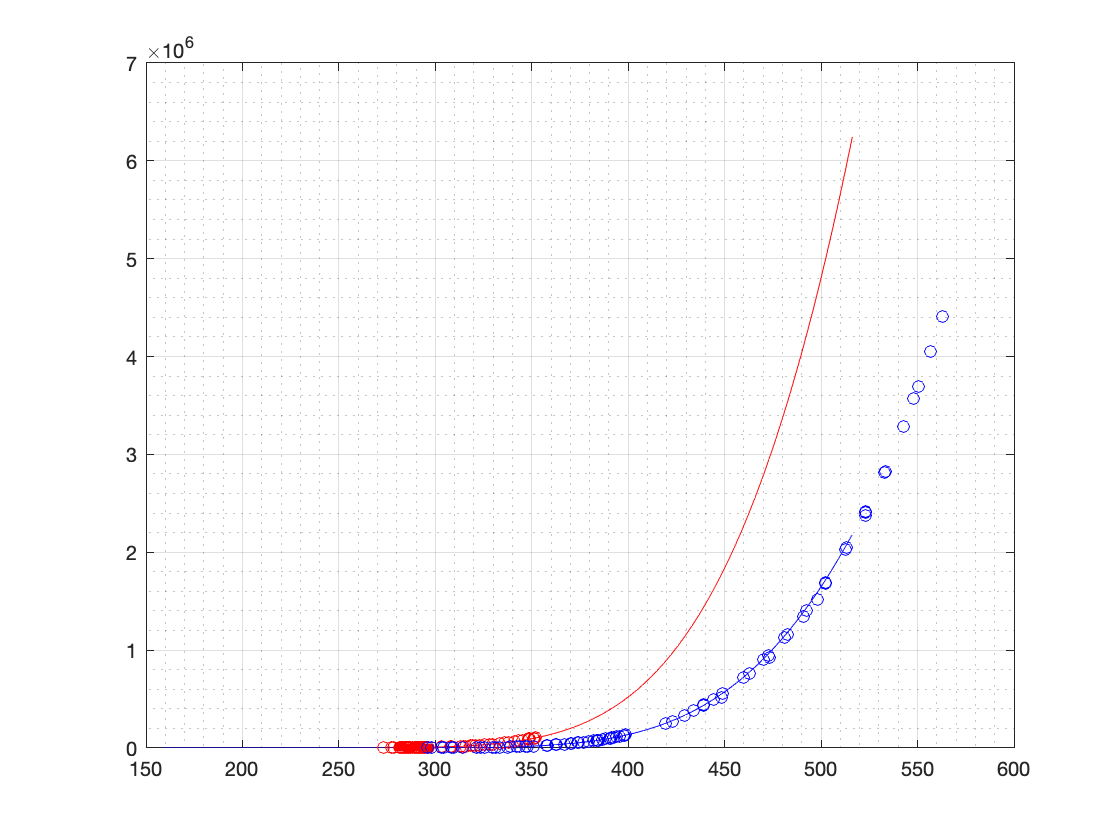

% Coefficient du Butanol
C_Butanol_KDB = [ -9.882614E+00  -9.127496E+03 8.672214E+01  1.428480E-06];
T_range_Butanol_KDB = [83.85 563.00];

% coefficient de l'éthanol
C_Ethanol_KDB = [ -5.089412E+00 -6.606453E+03 5.317030E+01 5.954048E-07];
T_range_Ethanol_KDB = [159.05 516.25];

% Détermination du  domaine commun 
T_range_KDB = [max(T_range_Ethanol_KDB(1), T_range_Butanol_KDB(1)) min(T_range_Ethanol_KDB(2), T_range_Butanol_KDB(2))];
T_KDB = linspace(T_range_KDB(1),T_range_KDB(2) , 100);

% Calcul des pressions de vapeur suivant la formule de Riedel modifiée
% Attention au changement d'unité ... kPa en Pa
P_Sat_Ethanol_KDB = P_Sat_KDB(T_KDB,C_Ethanol_KDB) * 1000;
P_Sat_Butanol_KDB = P_Sat_KDB(T_KDB,C_Butanol_KDB) * 1000;

PLOT_Ethanol_KDB = plot(T_KDB, P_Sat_Ethanol_KDB, '-r');
hold on
PLOT_Butanol_KDB = plot(T_KDB, P_Sat_Butanol_KDB, '-b');

% ajout des points expérimentaux DDBS

PLOT_Ethanol_DDBST = plot(P_Sat_Ethanol_DDBST(:,1), P_Sat_Ethanol_DDBST(:,2)*1000,'or');
PLOT_Butanol_DDBST = plot(P_Sat_Butanol_DDBST(:,1), P_Sat_Butanol_DDBST(:,2)*1000,'ob');
grid ;
grid minor;

Tout est  donc OK  ! 

## Calcul de l'équilibre liquide-vapeur

Partant du  constat que à pression P constante: 


$$y_1\cdot P = x_1\cdot P^{sat}_1 
$$



$$y_2\cdot P = x_2\cdot P^{sat}_2$$


on obtient : 


$$P = x_1\cdot P^{sat}_1
(T)+ (1-x_1)\cdot P^{sat}_2(T)
$$


si l'on se fixe arbitrairement une valeur de $x_1$, alors pour déterminer notre équilibre liquide-vapeur, il suffit de déterminer la température qui vérifie cette relation. Une solution consiste à  rechercher le "zéro" de la fonction suivante : 


$$f(T) = x_1\cdot P^{sat}_1
(T)+ (1-x_1)\cdot P^{sat}_2(T) - P = 0
$$


Dans notre cas, P = 101325 Pa. 

% Fonction Online dont on cherchera les "zéros"

Fonc_KDB = @(T,Coeff_1,Coeff_2,x,P) x*P_Sat_KDB(T,Coeff_1)+(1-x)*P_Sat_KDB(T,Coeff_2)-P ;

% détermination du  domaine de travail en x, fraction liquid éthanol

P = 101325 / 1000 % Le calcul est  en kPa pour les pressions de saturation via KDB

P = 101.3250

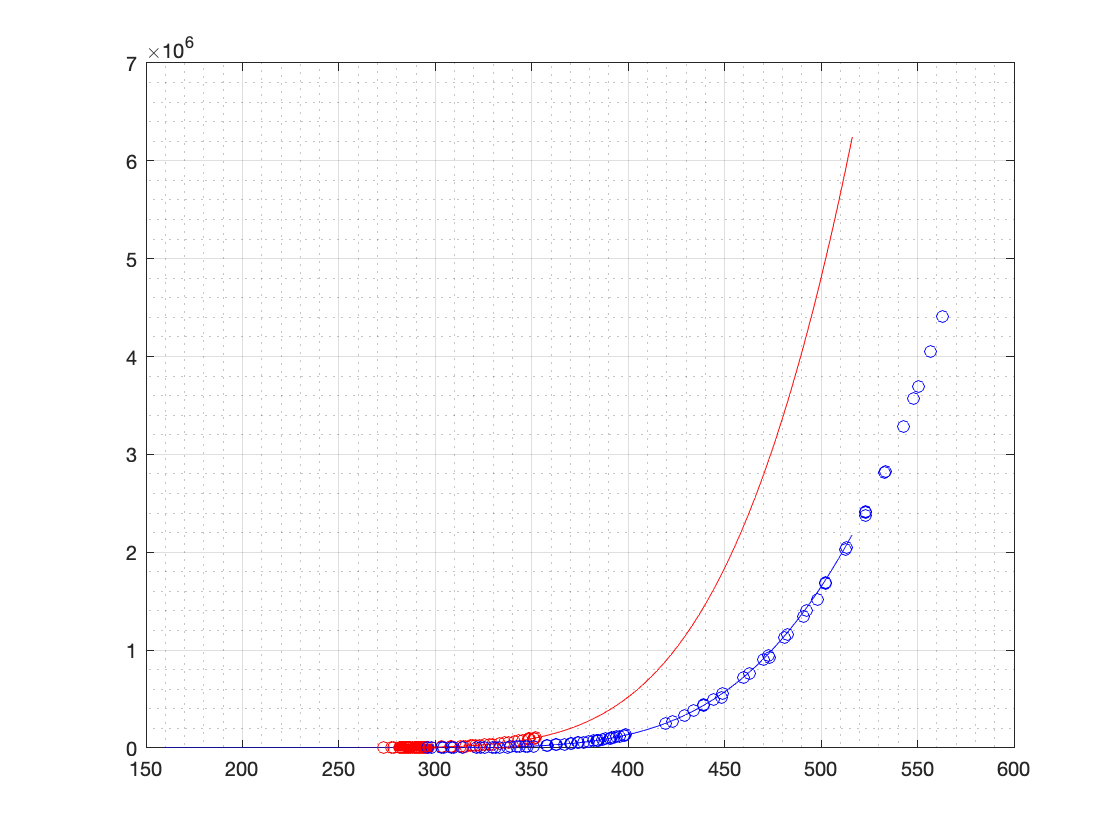

x = 0:0.01:1; 
N = size(x,2);
T0 = 325; % K, Valeur de départ pour la recherche de zéro. 


for i = 1:N
     [T(i)] = fzero(@(T) Fonc_KDB(T,C_Ethanol_KDB,C_Butanol_KDB,x(i),P),T0);
     [y(i)] = P_Sat_KDB(T(i),C_Ethanol_KDB )/P*x(i);
end


hold off

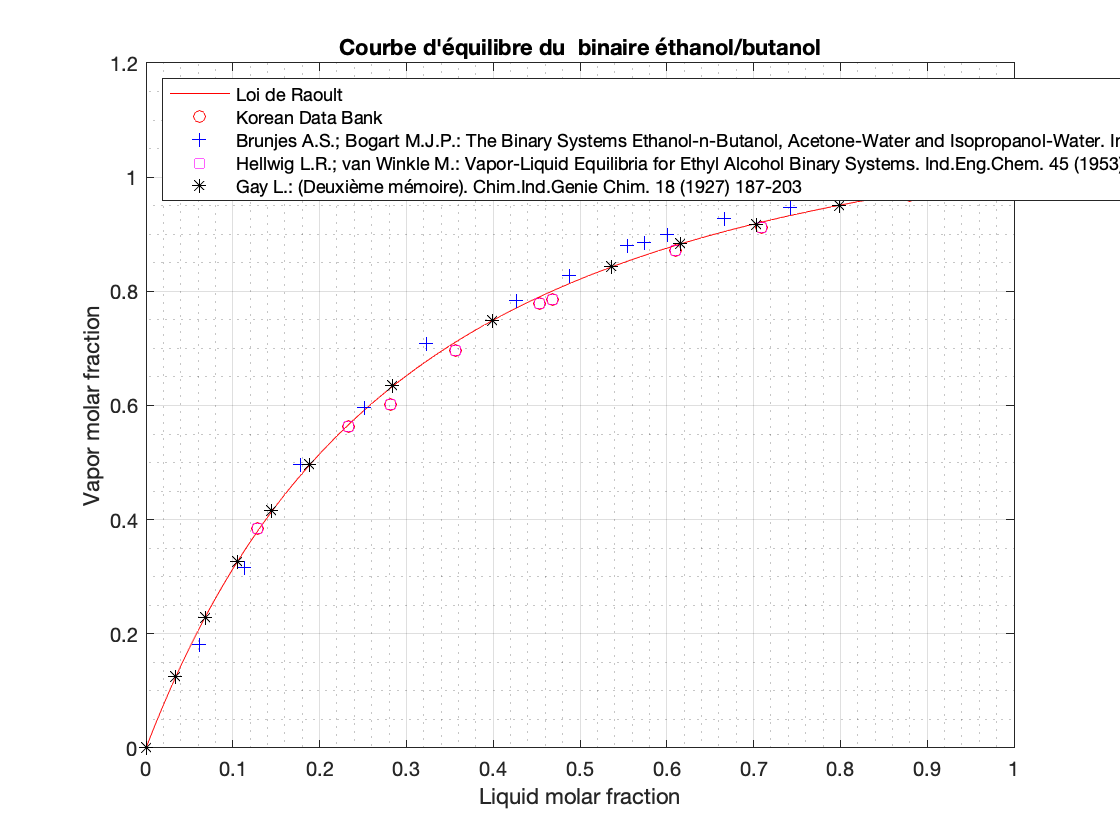

PLOT_CALC = plot(x,y,'r');
CALC = 'Loi de Raoult';
hold on 
PLOT_KDB = plot (VLE_KDB(:,3), VLE_KDB(:,4),'or');
PLOT_DDBST_Brunjes = plot (VLE_DDBST_Brunjes(:,2), VLE_DDBST_Brunjes(:,3),'+b');
PLOT_DDBST_Hellwig = plot (VLE_DDBST_Hellwig(:,2), VLE_DDBST_Hellwig(:,3),'sm');
PLOT_DDBST_Gay = plot (VLE_DDBST_Gay(:,2), VLE_DDBST_Gay(:,3),'*k');
grid 
grid minor
xlabel('Liquid molar fraction')
ylabel('Vapor molar fraction')
title('Courbe d''équilibre du  binaire éthanol/butanol')
legend ([PLOT_CALC PLOT_KDB,PLOT_DDBST_Brunjes,PLOT_DDBST_Hellwig,PLOT_DDBST_Gay],CALC,KDB, DDBST_Brunjes, DDBST_Hellwig, DDBST_Gay,'Location','northwest')
hold off

Nous pouvons donc raisonnablement considérer que le mélange éthanol / Butanol peut être considéré comme une solution idéale de gaz parfaits ! 

- En recherchant bien, vous devriez voir que les données utilisées par la KDB correspondent *de facto* à celle de Hellwig. Nous ne considèreront donc plus que les points correspondants à Brunjes, Hellwig et  Gay.

- On peut se poser raisonnablement la question sur la validité des mesures expérimentales de Gay ...

Passons donc au mélange eau-éthanol ...

## Bibliographie

[1]	W.M. Haynes, CRC Handbook of Chemistry and Physics, 97th Edition, CRC Press, 2016.

[2]	R.H. Perry, D.W. Green, Perry“s chemical engineer”s handbook; 8th ed., McGraw-Hill, New York, NY, 2008.

[3]	B. Poling, J. Prausnitz, J. O' Connell, The Properties of Gases and Liquids, McGraw Hill Professional, 2000. doi:10.1036/0070116822.